Piotr Sienkiewicz    324 887

Tadeusz Chmielik   324 856

**Splot jako metoda filtracji sygnałów**

Operacja splotu ma wiele zastosowań, jednak w przetwarzaniu sygnałów (i obrazów) jest stosowana najczęściej jako metoda filtracji. Za pomocą prostych filtrów można zrealizować m.in. operacje wygładzania sygnału, wyostrzania czy detekcji krawędzi. W ramach przykładu stworzymy sygnały sinusoidalny oraz prostokątny, które następnie zaszumimy:

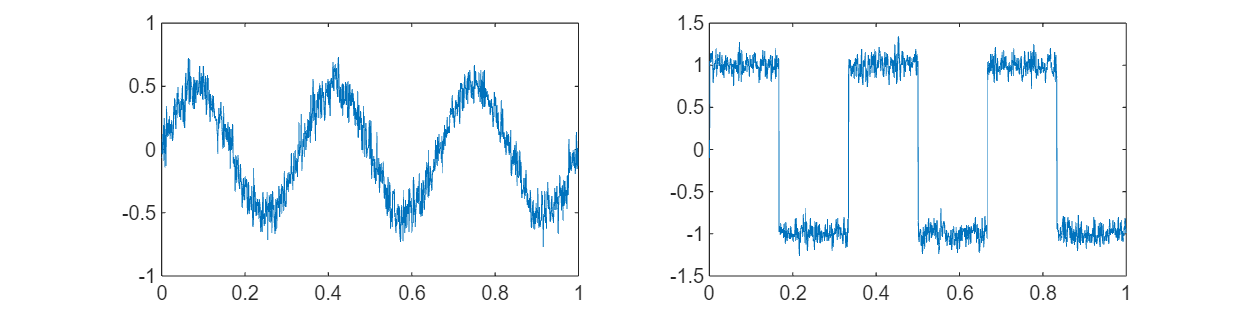

t=0:0.001:0.999;
sig_1 = 0.5*sin(6*pi*t) + 0.1 * randn(1, 1000);
sig_2 = sign(0.5*sin(6*pi*t)) + 0.1 * randn(1, 1000);
twoplots(t, sig_1, sig_2);

**Filtr uśredniający**

Charakter sygnału jest dość dobrze widoczny, jednak szum może przeszkadzać w jego analizie. Najprostszą metodą przetworzenia takiego sygnału jest uśrednienie wartości w pewnym oknie, dzięki czemu szum zostanie stłumiony. Filtr taki nazywamy filtrem średniej kroczącej, a jego realizacja przy użyciu splotu wymaga stworzenia bardzo prostego jądra. Filtr o rozmiarze N ma postać [1/N, 1/N, ..., 1/N]. Im dłuższy filtr stworzymy tym wygładzanie będzie lepsze, ale jednocześnie szybkie zmiany sygnału zostaną stłumione:

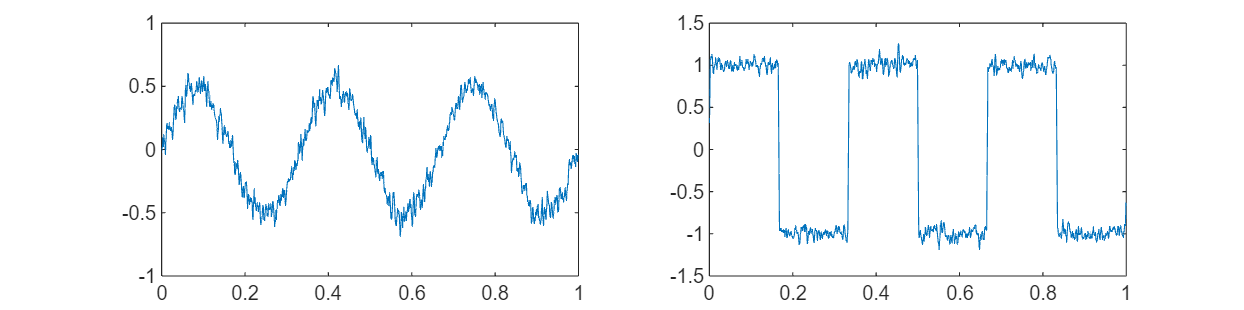

f3 = ones(1,3) / 3;
c3_1 = conv(sig_1, f3, 'same');
c3_2 = conv(sig_2, f3, 'same');
twoplots(t, c3_1, c3_2);

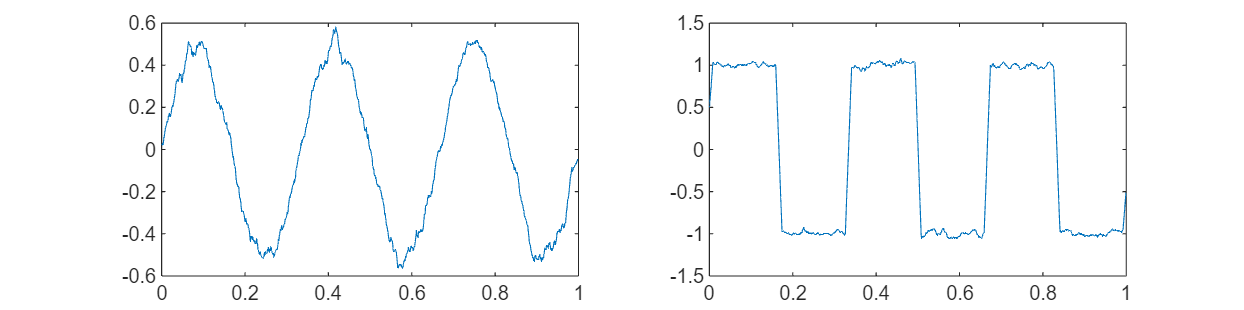

f15 = ones(1,15) / 15;
c15_1 = conv(sig_1, f15, 'same');
c15_2 = conv(sig_2, f15, 'same');
twoplots(t, c15_1, c15_2);

Zwiększenie wielkości filtra ma szczególnie widoczny wpływ na sygnał prostokątny, gdzie zbocze z pionowego zmieniło swoją stromość na dużo łagodniejsze. Inną wadę filtra uśredniającego można dostrzec po jego analizie częstotliwościowej. W skrócie: poddając jądro filtra przekształceniu do dziedziny częstotliwości możemy określić, jak filtr tłumi bądź wzmacnia poszczególne częstotliwości. Filtr wygładzający jest z natury filtrem dolnoprzepustowym, więc powinien przepuszczać niskie częstotliwości a tłumić wysokie. Spójrzmy więc na charakter najprostszego filtra 3-elementowego:

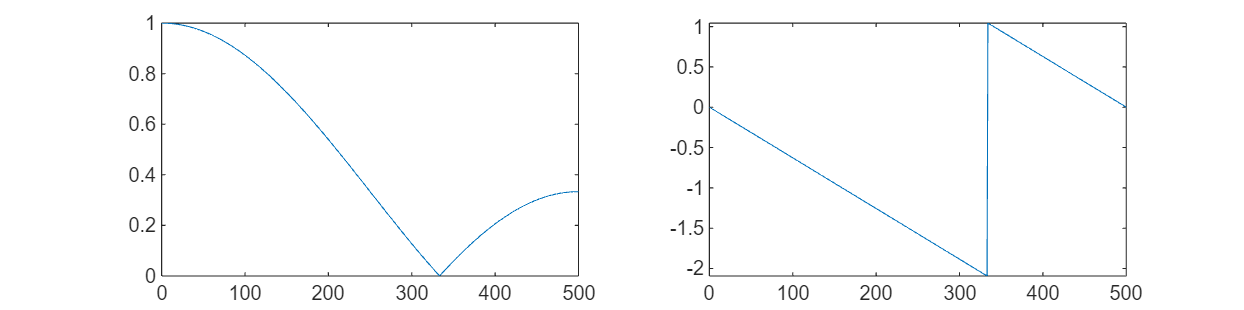

filtstat(f3);

Wykres amplitudowy możemy traktować jako wzmocnienie filtra dla różnych częstotliwości. Widać, że do ok. 2/3 skali faktycznie wzmocnienie spada, jednak później "odbija" się, a więc wyższe częstotliwości nie są całkowicie wygaszane. Co więdcej, stromość zbocza jest bardzo niska, więc filtr taki nie jest perfekcyjny. Zwiększając rozmiar filtra możemy wpłynąć na jego częstotliwość odcięcia (im dłuższy, tym niższa będzie częstotliwość odcięcia), jednak "dzwonienie" filtra pozostanie bez zmian.

**Filtr Gaussa**

Problemem filtra uśredniającego jest jednakowe traktowanie wszystkich punktów w danym oknie. Możemy przyjąć inne założenie, np, punkt centralny traktować jako najważniejszy, a im dalej od środka jądra tym wagę ustawiać na mniejszą. Popularnym rodzajem filtra tego typu jest filtr Gaussa. Dla trzech elementów jego dobrym przybliżeniem jest wektor [0.25, 0.5, 0.25], dla większych rozmiarów można użyć np. funkcji fspecial:

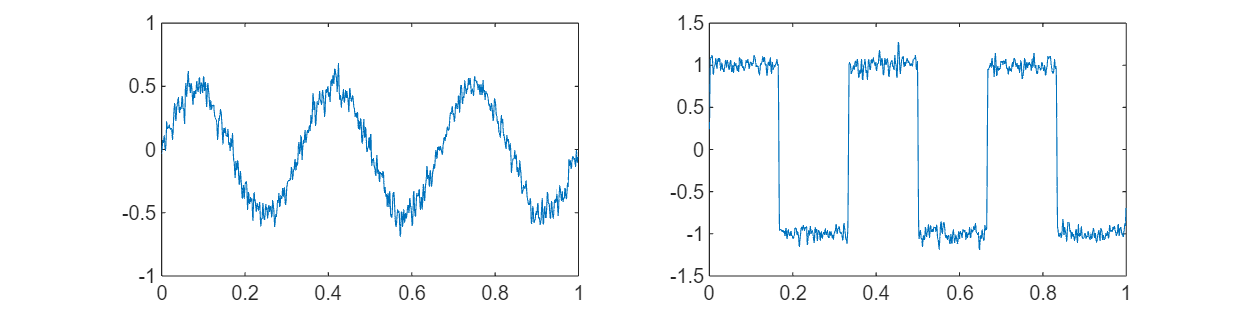

gaussian_mask = fspecial('gaussian', [1,  3], 1);
cg3_1 = conv(sig_1, gaussian_mask, 'same');
cg3_2 = conv(sig_2, gaussian_mask, 'same');
twoplots(t, cg3_1, cg3_2);

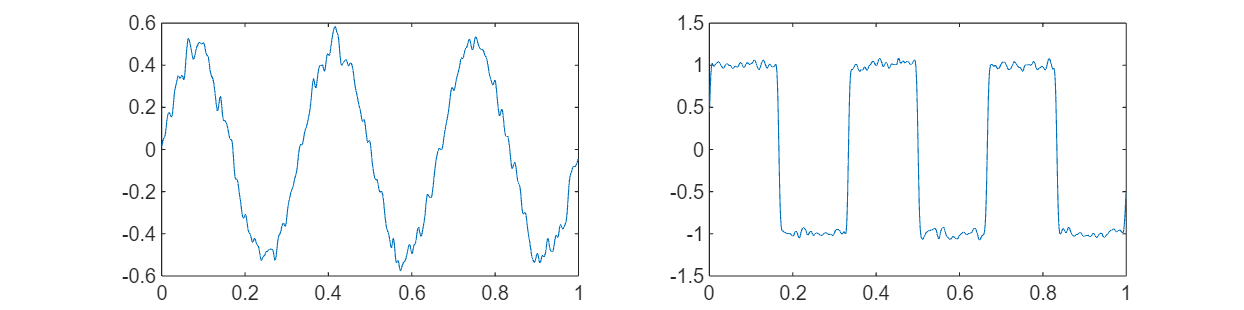

g15 = fspecial('gaussian', [1, 15], 3);
cg15_1 = conv(sig_1, g15, 'same');
cg15_2 = conv(sig_2, g15, 'same');
twoplots(t, cg15_1, cg15_2);

Filtr Gaussa ma dużo czystszą charakterystykę częstotliwościową, co widać nawet na przefilstrowanych sygnałach (nie ma fragmentów wysokich częstotliwości):

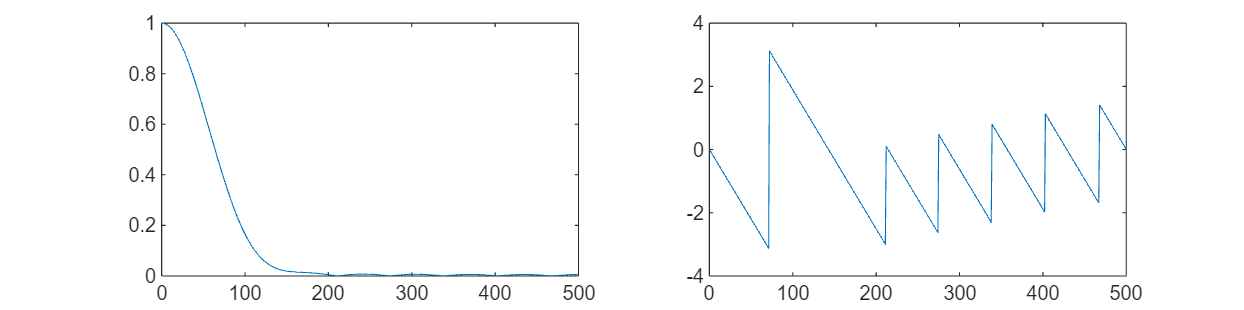

filtstat(g15);

Różnicę między filtrami uśredniającym i Gaussa widać szczególnie dobrze przy filtracji obrazów:

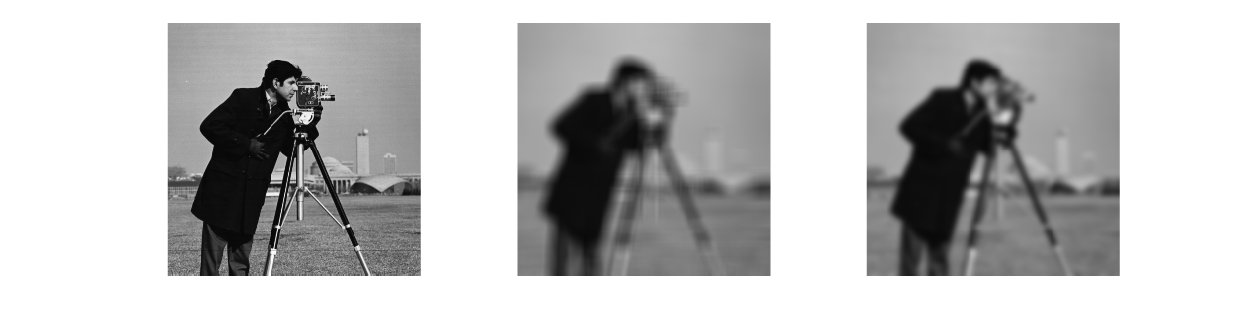

I=imread('cameraman.tif');
Ia = imfilter(I, fspecial('average', 15), 'replicate'); 
Ig = imfilter(I, fspecial('gaussian', 15, 3), 'replicate'); 
figure('Position', [10 10 1200 300]);
subplot(131);
imshow(I);
subplot(132);
imshow(Ia);
subplot(133);
imshow(Ig);

**Detekcja zbocza**

Inną grupą filtrów splotowych są filtry krawędziowe. Są to filtry górnoprzepustowe, których rolą jest wykrycie miejsc, gdzie zmiana sygnału jest duża. Zazwyczaj filtry takie sumują się do zera (w przeciwieństwie do wygładzających, które sumowały się do jedności), a najprostszym filtrem tego typu jest [1, 0, -1]:

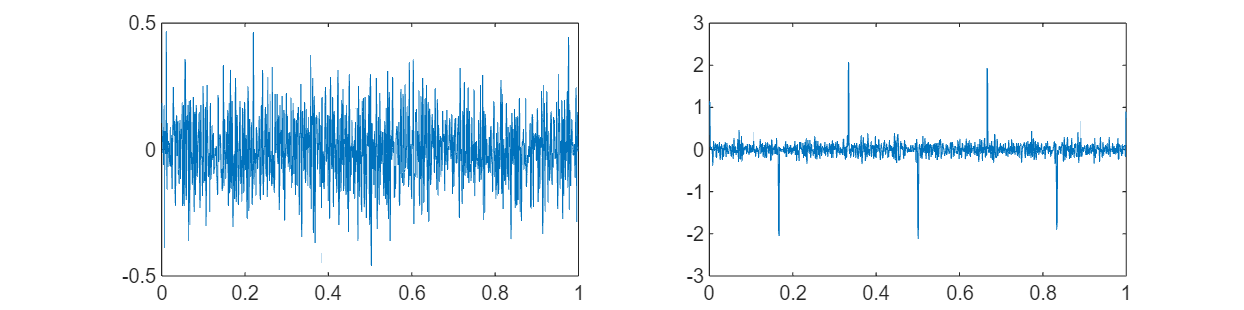

e3 = [1, 0, -1];
ce3_1 = conv(sig_1, e3, 'same');
ce3_2 = conv(sig_2, e3, 'same');
twoplots(t, ce3_1, ce3_2);

W przypadku sinusoidy odpowiedź jest zaszumiona, ale bez dużych skoków. Dla sygnału prostokątnego widać natomiast wyraźnie miejsca, w których sygnał miał zbocza opadające i narastające. Odpowiednie progowanie i dalsza analiza takiego sygnału pozwala na dość skuteczną detekcję zmian sygnału. 

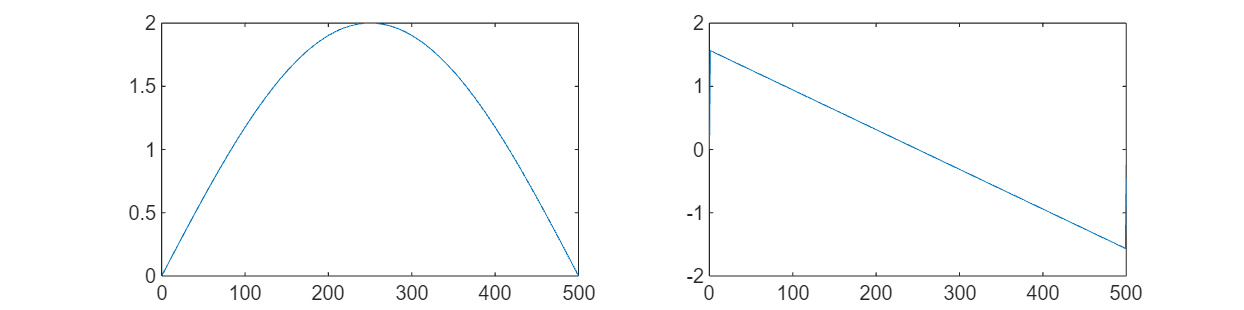

filtstat(e3);

**Autokorelacja jako metoda określania częstotliwości bazowej**

Splot dwóch sygnałów jest swego rodzaju miarą ich podobieńśtwa. Jeśli dokonamy splotu sygnału z jego kopią, przesuniętą o pewną liczbę próbek, będziemy mogli wyznaczyć jego samopodobieństwo. Wykonując tę operację dla całego przedziału wartości, w których sygnał został spróbkowany, otrzymamy autokorelację sygnału. Im wyższa wartość na wykresie autokorelacji, tym większe podobieństwo sygnału do swojej własnej, przesuniętej kopii.

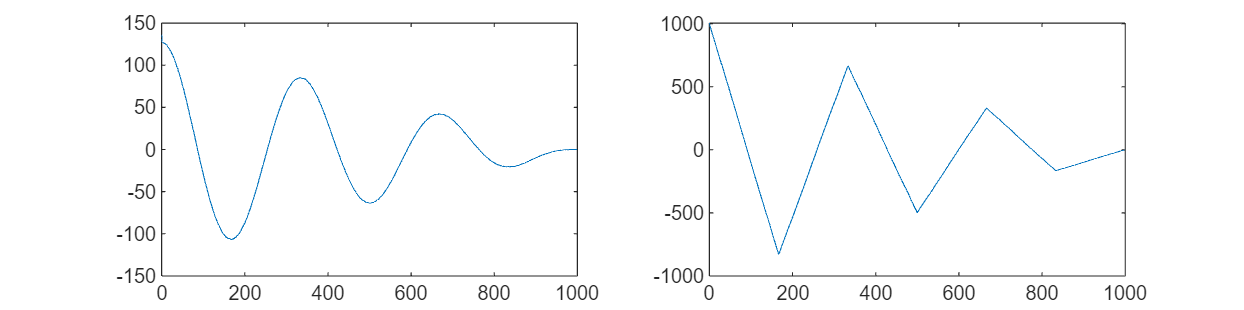

[r1, lags] = xcorr(sig_1);
[r2, lags] = xcorr(sig_2);
% wycięcie jedynie dodatnich przesunięć
r1 = r1(lags >= 0);
r2 = r2(lags >= 0);
lags = lags(lags>=0);
twoplots(lags, r1, r2);

function twoplots(t, s1, s2)
    figure('Position', [10 10 1200 300]);
    subplot(121);
    plot(t, s1);
    subplot(122);
    plot(t, s2);
end
function filtstat(f)
    nfft = 1000;
    fs = 1000;
    N = 3;
    
    f_ex = zeros(1, nfft);
    f_ex(1:size(f, 2)) = f;
    
    y=fft(f_ex);
    f_base = linspace(0, fs/2, nfft/2+1);
    amp = abs(y(1:nfft/2+1));
    phase = angle(y(1:nfft/2+1));
    
    twoplots(f_base, amp, phase);
end

## Analiza tętna

W zadaniu tym zastosowano kolejny sposób na wyznaczenie częstotliwości tętna na podstawie analizy obrazu nagranego na pierwszych zajęciach. Tym razem wykorzytano opisaną powyżej autokorelację do określenia częstotliwości bicia serca.

Poniższy fragment kodu jest identyczny jak ten z poprzednich zajęć i służy do zobrazowania zaburzeń jasności koloru czerwonego na nagraniu w czasie:

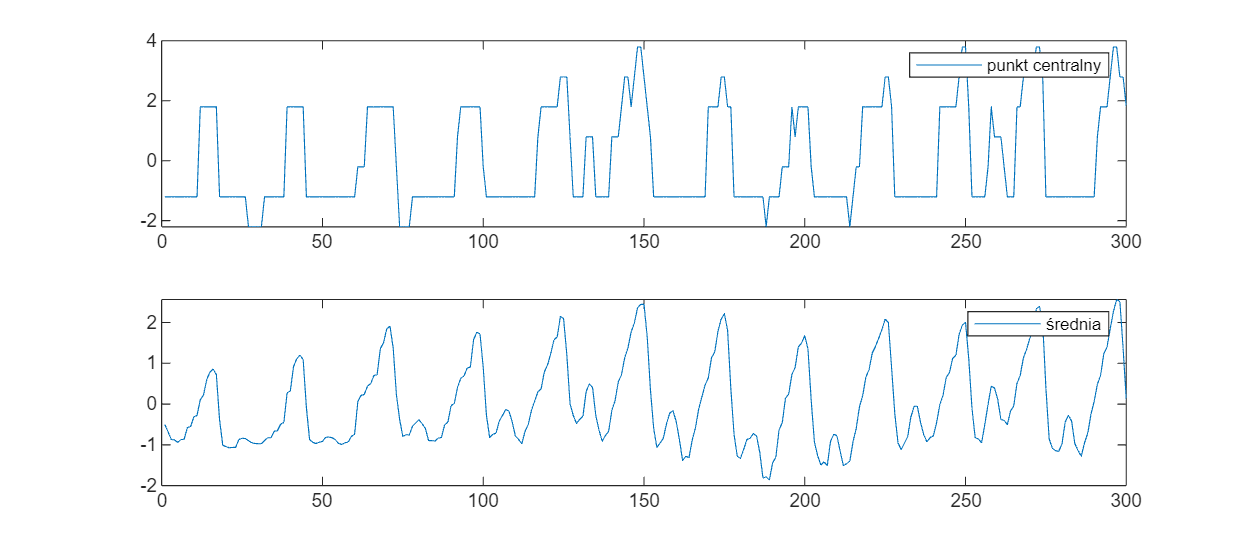

% Liczba ramek do wczytania (przy 10 sekundach i 30 FPS będzie to 300)
N = 300;
FPS = 30;

% wektor jasności
br = zeros(3, N);

use_video = 1;

if use_video
    % wczytywanie pliku wideo do analizy
    v = VideoReader('data/movie4.mp4');
    % v = VideoReader('data/movie_4.MOV');
else
    % lista obrazów do analizy
    imds = imageDatastore('./data/', 'FileExtension', '.jpg');
end

% wczytanie pierwszych N obrazów i analiza jasności
for i=1:N

    if use_video
        % dla pliku wideo ładowanie ramki z otwartego źródła
        I = read(v,i);
    else
        % wczytujemy obraz
        I = imread(imds.Files{i});
    end

    h = size(I,1);
    w = size(I,2);

    % wybieramy jedynie czerwoną składową obrazu
    I = I(:,:,1);

    % jasność punktu na środku obrazu
    br(1, i) = I(h/2, w/2);

    % wyznaczamy średnią z całego obrazu
    br(2, i) = mean(I, 'all');
end

% dla ułatwienia późniejszej analizy od razu można odjąć od sygnału składową stałą
br = br - mean(br, 2);


h = figure();
set(h,'Units','normalized','Position',[0 0 1 .7]); 
subplot(2,1,1);
plot(br(1,:));
legend('punkt centralny');
subplot(2,1,2);
plot(br(2,:));
legend('średnia');

### Filtracja sygnału

Aby ułatwić analizę powyższego sygnału, zaprojetowano prosty filtr Gaussa. Co prawda podczas testów okazało się, że użycie filtra nie zmienia ostatecznego wyniku przy wykorzystaniu autokorelacji do wyznaczania częstotliwości sygnału (dlatego właśnie jest to bardzo dobra metoda w przypadku zaszumionych sygnałów z dużą ilością zakłóceń, dzięki czemu jest ona używana chociażby w technikach transmisji OFDM), jednakże do celów tego ćwiczenia zastosowano filtr pozwalający otrzymać sygnał łatwiejszy do jego wizualnej oceny.

Najlepszy efekt będący kompromisem między długością maski (co przekłada się na liczbę wykonywanych obliczeń) a jakością sygnału na wyjsciu uzyskano dla okna o długości 10 oraz odchyleniu standardowym 5. Poniższy wykres przedstawia kolejne wartości wygenerowanego okna o tych parametrach:

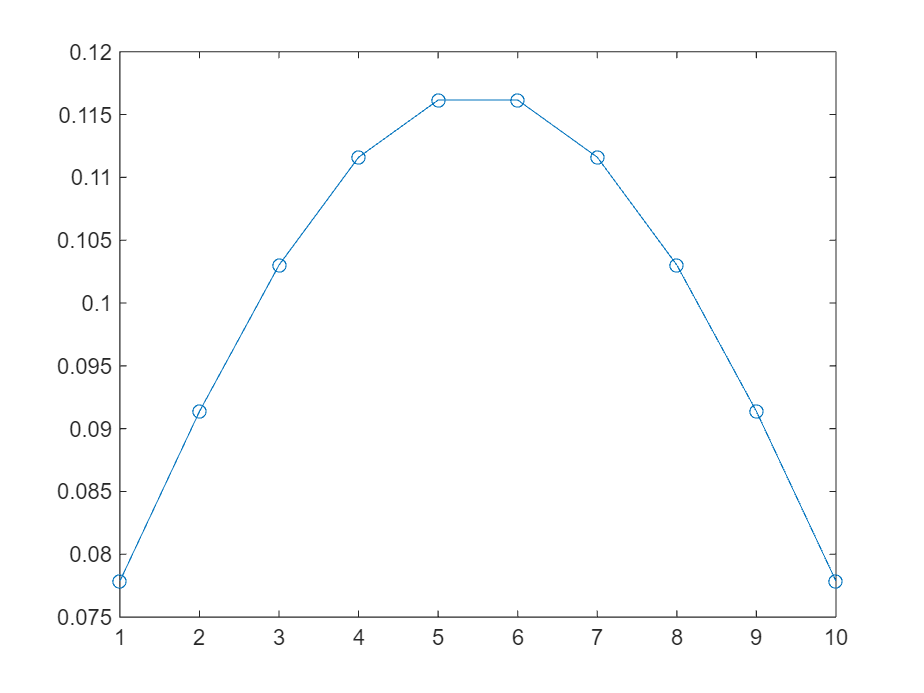

figure;
gaussian_mask = fspecial('gaussian', [1,  10], 5);
filtered_signal = conv(br(2,:), gaussian_mask, 'same');
plot(gaussian_mask, '-o');

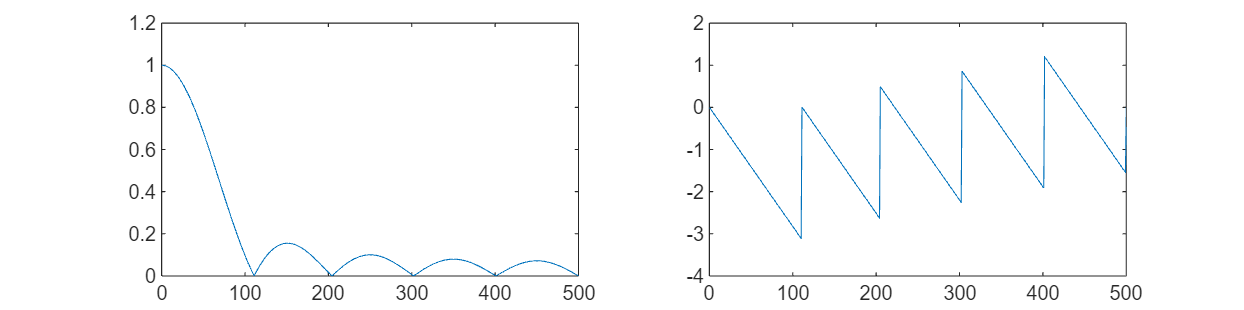

filtstat(gaussian_mask);

Powyższe wykresy przedstawiają charakterystykę amplitudową oraz fazową. Jak widać, filtr ten ma dość dużą szybkość opadania charakterystyki amplitudowej oraz nie za duże oscylacje wzmocnienia w paśmie zaporowym. Nie jest to idealna charakterystyka, jednakże wystarczająca do tego zastosowania.

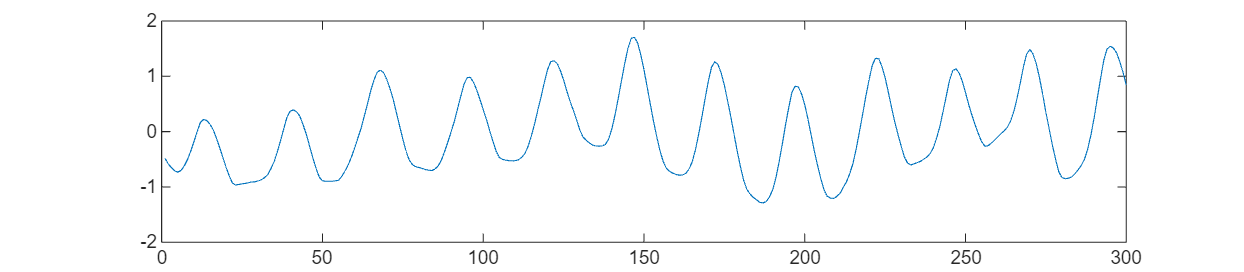

h = figure;
set(h, 'Units','normalized','Position',[0 0 1 .35]); 
plot(filtered_signal);

Na wykresie tym przedstawiono sygnał tętna po filtracji. Od razu zauważyć można usunięcie małych pików, które występowały między poszczególnymi uderzeniami serca, a które wynikały z natury chwilowych zmian ciśnienia krwi podczas pracy serca.

### Wyznaczanie autokorelacji

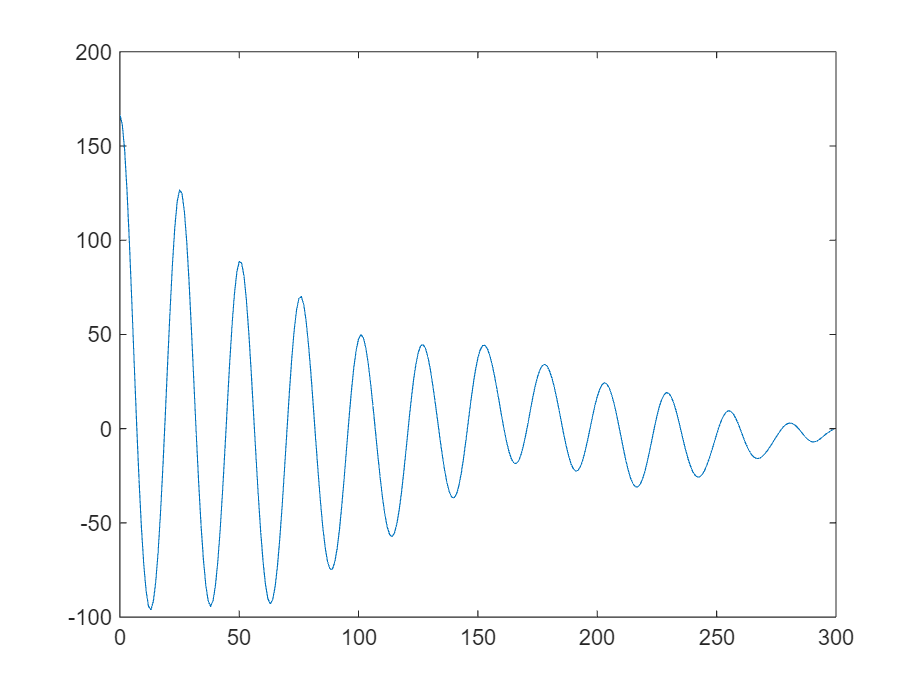

[r1, lags] = xcorr(filtered_signal);

% wycięcie jedynie dodatnich przesunięć
r1 = r1(lags >= 0);
lags = lags(lags>=0);
figure;
plot(lags, r1);

Na powyższym rysunku znajduje się wykres korelacji dla dodatnich przesunięć. 

### Wyznaczanie tętna

Sygnał autokorelacji wykorzystano do wzynaczenia częstotliwości sygnału. W tym celu wyznaczono lokalizację ekstremów sygnału. Jeżeli znaleziono więcej niż 1 ekstremum, możliwe jest określenie częstotliwości. Aby poprawić rozdzielczość i dokładność pomiarów, wylicza się odległość między pierwszym a ostatnim znalezionym ekstremum, zamiast brać jedynie odległość między dwoma sąsiednimi ekstremami. Następnie tą odległość dzieli się przez liczbę ekstremów - 1, uzyskując średni okres wyznaczony w ilości próbek, mnożąc go razy *1/FPS *uzyskuje się okres wyrażony w sekundach. Mając to wyznaczone, wyliczenie BPM jest już oczywiste.

[pks, loc] = findpeaks(r1, "MinPeakDistance", 10, "MinPeakProminence", 20);

if numel(loc) > 1
    total_lag = loc(end) - loc(1);
    average_lag = total_lag / (numel(loc) - 1);
    lag_s = average_lag * 1/FPS;
    freq = 1 / lag_s;
else
    freq = NaN;
end
freq

freq = 1.1739

BPM = freq * 60

BPM = 70.4348

### Ocena rozdzielczości pomiaru

Na pierwszych zajęciach analizując odlęgłości między pikami w sygnale otrzymano wartość  `70.4626`, natomiast na laboratoriach, gdzie wykorzytywano FFT, otrzymano `72.00`. Jak widać, użycie FFT daje najsłabszą rozdzielczość, co wynika z minimalnej możliwej do uzyskania szerokości kubełka przy danej liczbie próbek, natomiast metoda autokorelacji oraz określania odległości między pikami w dziedzinie czasu dają podobne wyniki. Jednak to właśnie metoda autokorelacji daje wyniki najbardziej zbliżone do rzeczywistej wartości, gdyż jest najbardziej odporna na szumy i zakłócenia w sygnale. Za pomocą autokorelacji można określić częstotliwość sygnału nawet w przypadku takiej ilości szumów, która uniemożliwiałaby jakąkolwiek wizualną analizę sygnału w dziedzinie czasu. Ta właściwość wynika z tego, że szum i zakłócenia mają charakter losowy, a więc autokorelacja dla nich jest prawie zerowa. W tym zadaniu w celu poprawy rozdzielczości wyznacza się odległość między pierwszym i ostatnim pikiem autokorelacji (w przypadku brania odległości tylko między sąsiednimi pikami wartość tętna wynosiła `72`). Tak więc można powiedzieć, że w tym przypadku rozdzielczość pomiaru jest ograniczona tylko ilością próbek i częstotliwością próbkowania. Można też zastosować wzór na rozdzielczość metody z pierwszych laboratoriów:


$$\frac{1}{FPS} \cdot \left( \frac{samples}{counter - 1} - \frac{samples - 1}{counter - 1} \right)$$


gdzie *FPS *to liczba klatek na sekundę, *samples* to liczba próbek między pierwszym a ostatnim ekstremum autokorelacji, a *counter* to liczba znalezionych ekstremów. Tak więc aby zwiększyć rozdzielczość można zwiększyć ilość klatek na sekucndę i/lub długość nagrania, jednak wydaje się to być niepotrzebne, gdyż rozdzielczość i dokładność otrzymana w tej metodzie jest i tak bardzo duża. 